# Ejercicios 31/05

**Team members:**

Javier Cabrera

Julia Gasull

**Link: **[https://drive.matlab.com/sharing/49eb5fa6-0641-425c-a130-9cf41b2e1058](https://drive.matlab.com/sharing/49eb5fa6-0641-425c-a130-9cf41b2e1058)

clc
clear
close all

## Exercise 4

### Part A

% clear
% 
% load("3B.mat")
% dx = DXform(map);
% dx.plan([92 10], 'animate')
% dx.query([8 85], 'animate')

Comment: We have the following error in here:

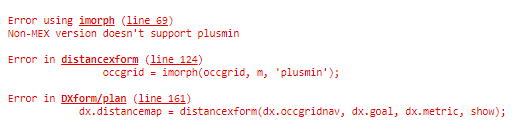

## Exercise 5

clear
load house
ds = Dstar(house);
ds.plan(place.kitchen)

245184 iterations


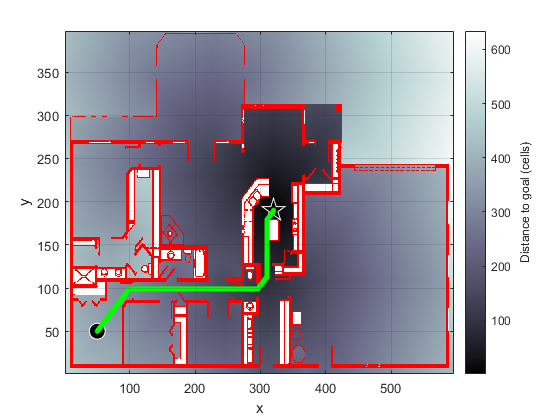

ds.query(place.br3, 'animate')

### Part A

ds.modify_cost([150,270; 150,260], 0.1)
ds.plan()

1194375 iterations


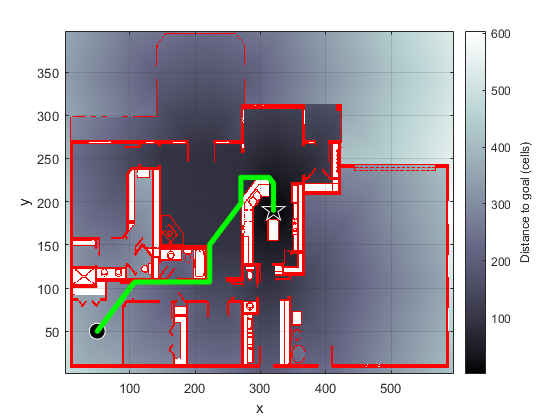

ds.query(place.br3, 'animate')

Comment: We lowered the cost on the majority of the living room so that the robot prefers going through this room.

### Part B

ds.modify_cost([300,360; 210,211], Inf)
ds.plan()

290286 iterations


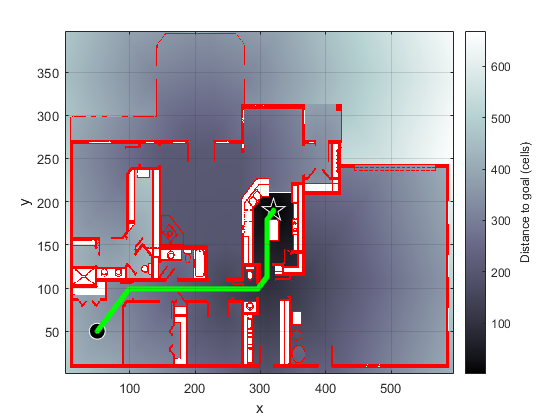

ds.query(place.br3, 'animate')

Comment: We blocked the kitchen's upper entrance by adding a lot of cost in a line.

## Exercise 6

### Part A

% clear
% load house
% prm = PRM(house);
% randinit(9);
% path_length = zeros(100);
% for i = 1:100
%     prm.plan('npoints',150)
%     try
%         p = prm.query(place.br3, place.kitchen);
%     catch ME
%         p = [];
%     end
%     len = 0;
%     if (length(p) > 2)
%         for j = 1:(length(p)-1)
%             len = len + distance(p(j,1:2)', p(j+1,1:2)');
%         end
%         path_length(i) = len;
%     end
% end

We first iterated over all the nodes to save the path length between all of them and then we saved the resulting matrix.

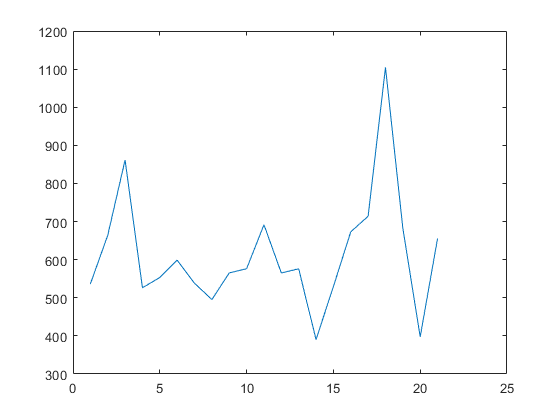

load('6a.mat')
path_length = nonzeros(path_length);
figure
plot(path_length)

length(path_length)

ans = 21

%save('6a.mat', 'path_length')

### Part B

% prm.distthresh = 110;
% prm.distthresh0 = 110;
% randinit(9);
% path_length = zeros(100);
% for i = 1:100
%     prm.plan('npoints',150)
%     try
%         p = prm.query(place.br3, place.kitchen);
%     catch ME
%         p = [];
%     end
%     len = 0;
%     if (length(p) > 2)
%         for j = 1:(length(p)-1)
%             len = len + distance(p(j,1:2)', p(j+1,1:2)');
%         end
%         path_length(i) = len;
%     end
% end

We first defined the threshold to 110 and then saved the results.

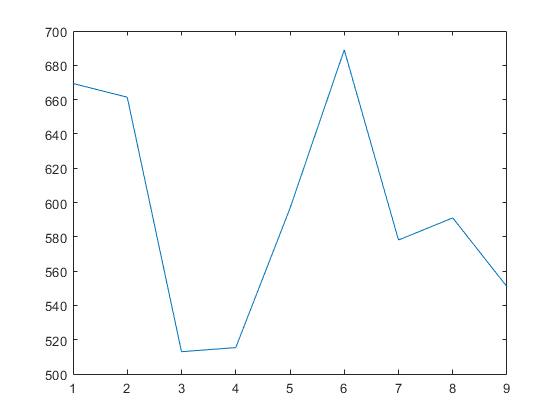

load('6b1.mat')
path_length = nonzeros(path_length);
figure
plot(path_length)

length(path_length)

ans = 9

%save('6b1.mat', 'path_length')

When checking the differences we can observe that there is a decrease from 21% to 9% available paths when using the 110 threshold.

% prm.distthresh = 240;
% prm.distthresh0 = 240;
% randinit(9);
% path_length = zeros(100);
% for i = 1:100
%     prm.plan('npoints',150)
%     try
%         p = prm.query(place.br3, place.kitchen);
%     catch ME
%         p = [];
%     end
%     len = 0;
%     if (length(p) > 2)
%         for j = 1:(length(p)-1)
%             len = len + distance(p(j,1:2)', p(j+1,1:2)');
%         end
%         path_length(i) = len;
%     end
% end

On the second analysis, we used 240 as the threshold and saved the results.

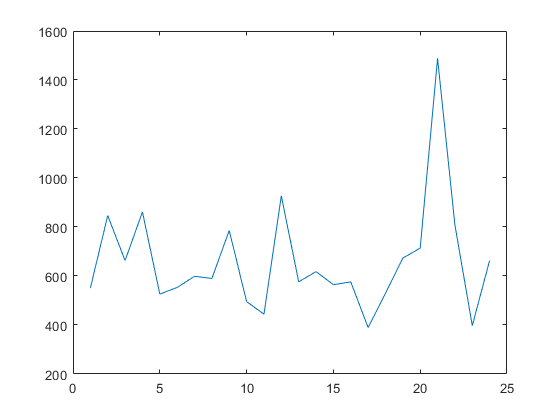

load('6b2.mat')
path_length = nonzeros(path_length);
figure
plot(path_length)

length(path_length)

ans = 24

%save('6b2.mat', 'path_length')

By increasing the threshold, we can observe a small increase of 3% in the number of viable roads.

## Exercise 7

### Part A

lp = Lattice();
lp.plan('iterations',8)

780 nodes created


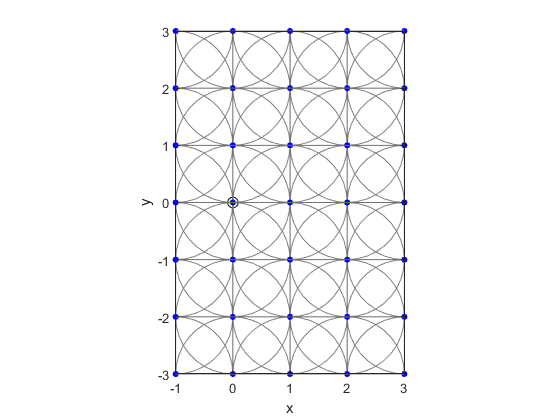

limits = [-1, 3, -3. 3];
figure
lp.plot()
axis(limits)

Based on testing, the minimum iterationes required to form a complete Lattice is 8.

If we use 7 iterations we can observe some missings on the corners:

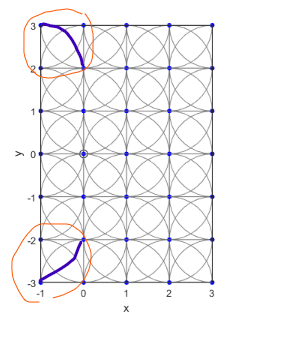

### Part B

lp = Lattice();
for i=1:8
    lp.plan('iterations', i)
end

4 nodes created
13 nodes created
38 nodes created
97 nodes created
209 nodes created
372 nodes created
566 nodes created
780 nodes created


Comment: We can see that the creation of nodes is practically exponential.

### Part C

To calculate the arc resulting from the indicated steering angle, we use the wheelbase expressed in mm to count it as an integer, which allows us a well-defined grid.

wheelbase = 4500; % [mm]
steering_deg = 60;
res = wheelbase / (2 * sin(steering_deg*pi/180));

lp = Lattice('grid', res);
lp.plan('iterations', 1);

4 nodes created


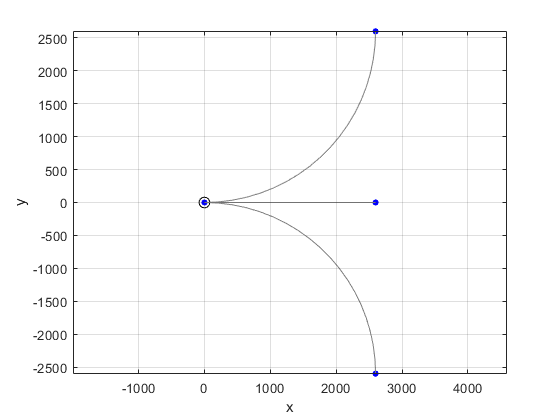

lp.plot()

### (optional) Part D

By increasing the cost of left turns so that the path prefers to make right turns, we observe that it is impossible to make only right turns with the map size and the position required. 

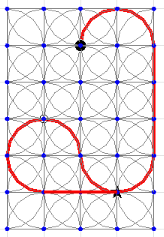

We need to either increase the map or change the position of the goal. In our case we increased the map 1 coordinate downwards.

clear
lp = Lattice('cost', [1 10 1]);
lp.plan('iterations', 8);

780 nodes created


start = [1  2 pi/2];
goal  = [2 -2    0];
p = lp.query(start, goal);

A* path cost 10


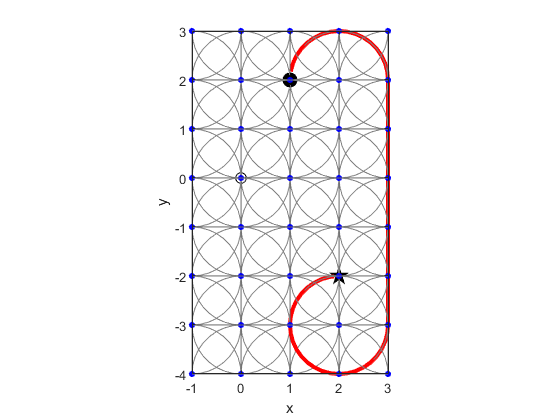

figure
lp.plot()
limits = [-1 3 -4 3];
axis(limits)

### (optional) Part E

We based on the map generated for the D part.

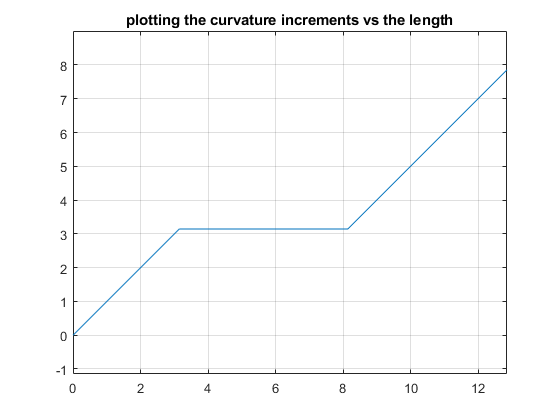

straight = 1;
curve = (2*pi*1)/4;
q = zeros(length(p), 2);
rad = p(1,3);
q(1,1) = 0;
q(1,2) = 0;
for i=2:length(p)
    rad2 = p(i,3);
    if rad == rad2
        q(i,1) = q(i-1,1) + straight;
        q(i,2) = q(i-1,2) ;
    else
        q(i,1) = q(i-1,1) + curve;
        q(i,2) = q(i-1,2) + pi/2;
    end
    rad = rad2;
end
figure
plot(q(1:end,1),q(1:end,2))
title('plotting the curvature increments vs the length')
grid on
axis equal

Comment: We can see stable moments when the route goes in a straight line, and increases in the curvature when it makes turns.

## Exercise 8

### Part A

randinit(123456789)
load road
car = Bicycle('steermax', 0.5);

rtt_o = RRT(car, road, 'npoints', 1000, 'root', [10 50 0], 'simtime', 4);
rtt_o.plan();

A* path cost 7


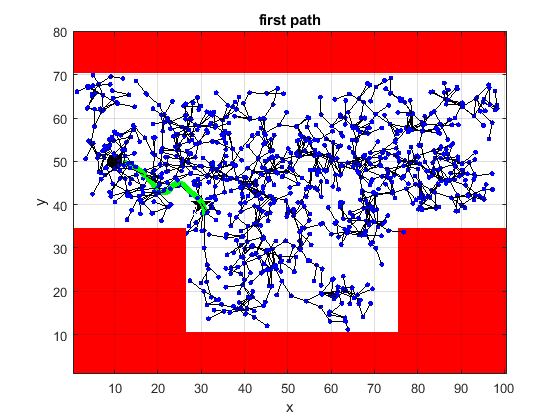


p1 = rtt_o.query([10 50     0], [30 40 -pi/2]); figure; rtt_o.plot(p1); title("first path")

A* path cost 25


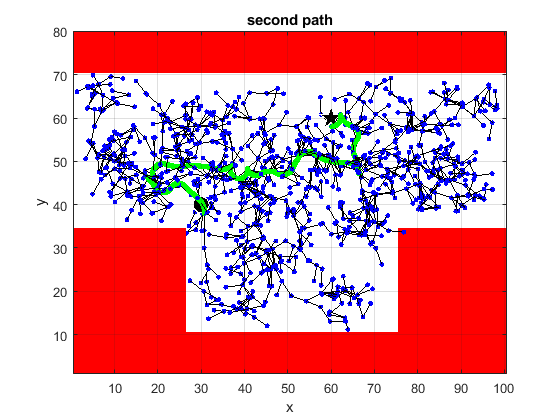

p2 = rtt_o.query([30 40 -pi/2], [60 60     0]); figure; rtt_o.plot(p2); title("second path")

A* path cost 15


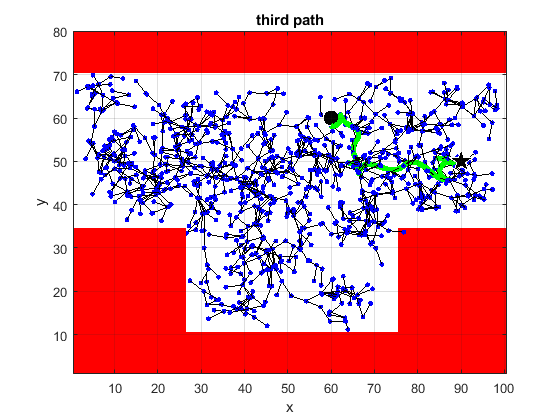

p3 = rtt_o.query([60 60     0], [90 50    pi]); figure; rtt_o.plot(p3); title("third path")

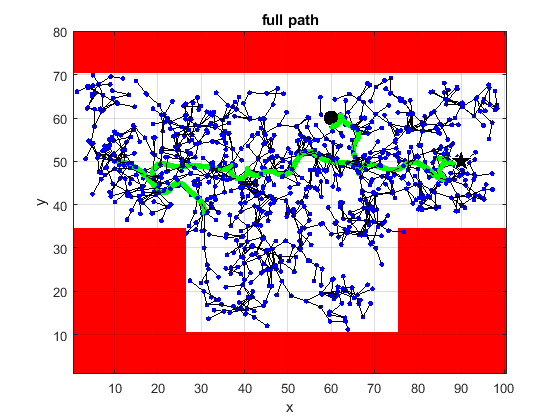


p_final_original = [p1;p2;p3];
figure; rtt_o.plot(p_final_original); title("full path")

We can see that, for each p_i, the robot have done correctly every path, as well as the full one.

### Part B

#### Changing steermax

randinit(123456789)
load road
car = Bicycle('steermax', 0.8);

rtt_o = RRT(car, road, 'npoints', 1000, 'root', [10 50 0], 'simtime', 4);
rtt_o.plan();


p1 = rtt_o.query([10 50     0], [30 40 -pi/2]); 

A* path cost 11


p2 = rtt_o.query([30 40 -pi/2], [60 60     0]); 

A* path cost 23


p3 = rtt_o.query([60 60     0], [90 50    pi]); 

A* path cost 19



p_final_steermax = [p1;p2;p3];
figure; rtt_o.plot(p_final_steermax); title("changing steermax");

When we change the max steering that the path can make, we observe that it cannot achieve the endpoint correctly.

#### Changing npoints

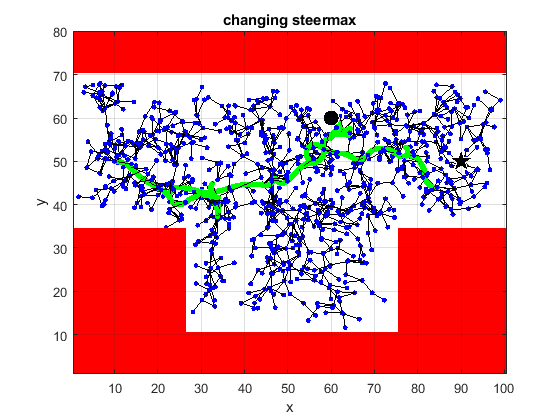

randinit(123456789)
load road
car = Bicycle('steermax', 0.5);

rtt_o = RRT(car, road, 'npoints', 2000, 'root', [10 50 0], 'simtime', 4);
rtt_o.plan();


p1 = rtt_o.query([10 50     0], [30 40 -pi/2]); 

A* path cost 7


p2 = rtt_o.query([30 40 -pi/2], [60 60     0]); 

A* path cost 27


p3 = rtt_o.query([60 60     0], [90 50    pi]); 

A* path cost 17



p_final_npoints = [p1;p2;p3];
figure; rtt_o.plot(p_final_npoints); title("changing npoints");

When adding more points to the map, the path is similar to the original one, with some minor changes.

#### Changing simtime

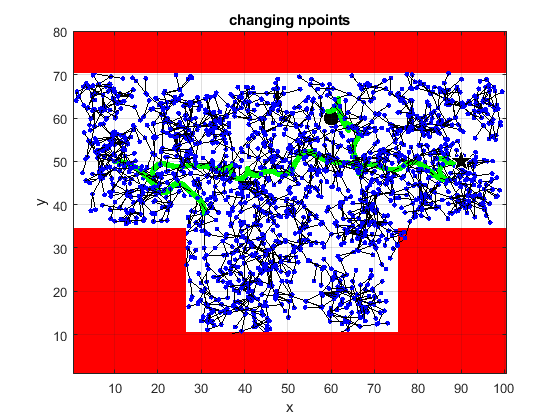

randinit(123456789)
load road
car = Bicycle('steermax', 0.5);

rtt_o = RRT(car, road, 'npoints', 1000, 'root', [10 50 0], 'simtime', 20);
rtt_o.plan();


p1 = rtt_o.query([10 50     0], [30 40 -pi/2]); 

A* path cost 9


p2 = rtt_o.query([30 40 -pi/2], [60 60     0]); 

A* path cost 15


p3 = rtt_o.query([60 60     0], [90 50    pi]); 

A* path cost 17


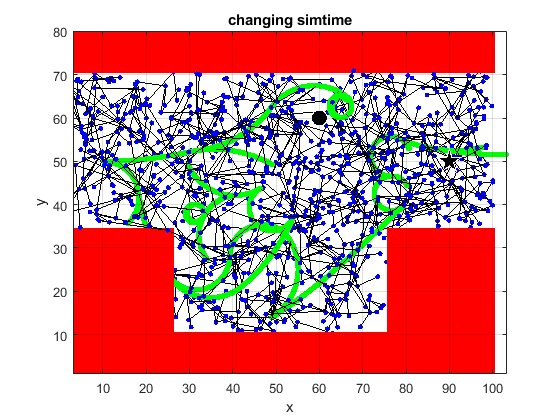


p_final_simtime = [p1;p2;p3];
figure; rtt_o.plot(p_final_simtime); title("changing simtime");

If we increase the time of the path, the resulting path is noticeably larger than before.

### (optional) Part C

randinit(123456789)

len = length(p_final_original)

len = 1960

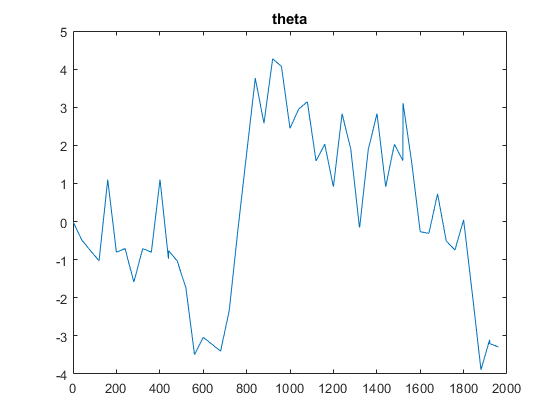

all_theta = zeros(1,len);
all_speed = zeros(1, len-1);
time = 1; % [m/s]

all_theta(1) = p_final_original(1,3);
for i=2:len
    all_theta(i) = p_final_original(i,3);
    all_speed(i) = distance(p_final_original(i,1:2)',p_final_original(i-1,1:2)');
end

% steering angle
plot(all_theta); title("theta");

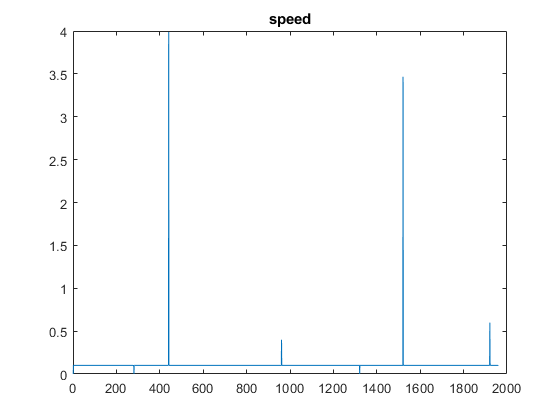

plot(all_speed); title("speed");

If we plot the steering made during the path (in radians), we can observe very large turns in each of the directions, but more common on one of them (positive).

The speed is maintained almost constant throughout all the route, with 2 big peaks of velocity.